# Extracting point clouds

Using this MATLAB live script, you can interactively preprocess the data from your extraction points

addpath("C:\Users\agori\Documents\MATLAB\3D-Sea-Ice\ExtractClouds");
addpath("C:\Users\agori\OneDrive - University of Cape Town\ROS2 Validation");

pathname="C:\Users\agori\OneDrive - University of Cape Town\ROS2 Validation\2blocks\";
tic
[all_cloudsLiDAR, arrRSraw, fnames] =ros2GetRawslim(pathname);
%[minsz, testout] = getMinSz(all_cloudsLiDAR,fnames);
toc

Elapsed time is 106.528966 seconds.


scanOrder="FEDCBAHG";
save("Blocks2Raw.mat");

load("Blocks2Raw.mat");

#### getMinSz: helps to determine number of point clouds to use by checking the minimum size of your data collection

[minsz, testout] = getMinSz(all_cloudsLiDAR,fnames);

               Filenames               NClouds
    _______________________________    _______

    {'rosbag2_2022_12_07-12_16_02'}      149  
    {'rosbag2_2022_12_07-12_16_50'}      129  
    {'rosbag2_2022_12_07-12_17_52'}      129  
    {'rosbag2_2022_12_07-12_18_43'}      101  
    {'rosbag2_2022_12_07-12_19_39'}      124  
    {'rosbag2_2022_12_07-12_20_25'}      106  
    {'rosbag2_2022_12_07-12_21_07'}       90  
    {'rosbag2_2022_12_07-12_21_50'}      101  

Min size=90


Error using toc
You must call TIC without an output argument before calling TOC
without an input argument.

### Cropping to the desired region of interest (ROI)

An approximate manual cropping assists in the 3D reconstruction process. Here you can edit z_roi, y_roi and x_roi and see how this impacts the display. Once you are happy with this, the **cropMerge **function can be run where you decide how many messages you want to concatenate and what your roi you want to crop.

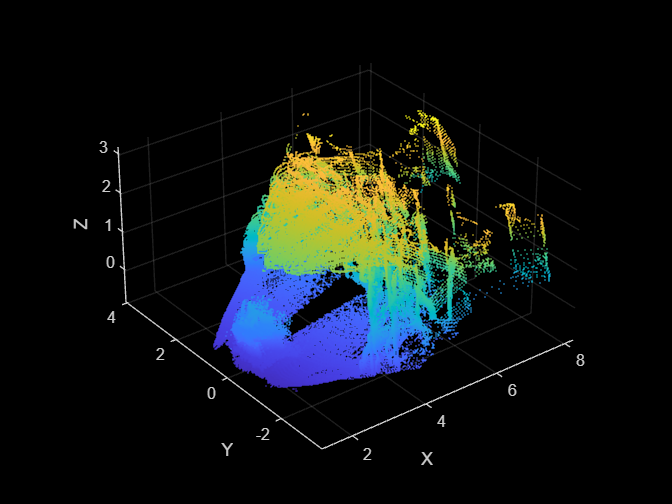

pcshow(testout,"AxesVisibility","on");
xlabel('X');
ylabel('Y');
zlabel('Z');


%z_roi=[-inf,1];
%y_roi=[-3,3];
%x_roi=[1.2,3];

z_roi=[-inf,inf];
y_roi=[-inf,inf];
x_roi=[-inf,inf];

roi=[x_roi,y_roi,z_roi];

%zlim(z_roi);
%ylim(y_roi);
%xlim(x_roi);

### cropMerge

dummyArr={all_cloudsLiDAR{5},all_cloudsLiDAR{6}};

tic
%[cat_pointCloudArray] = cropMerge(roi,80,all_cloudsLiDAR);
[cat_pointCloudArray] = cropMerge(roi,80,dummyArr);
toc

Elapsed time is 9.563228 seconds.


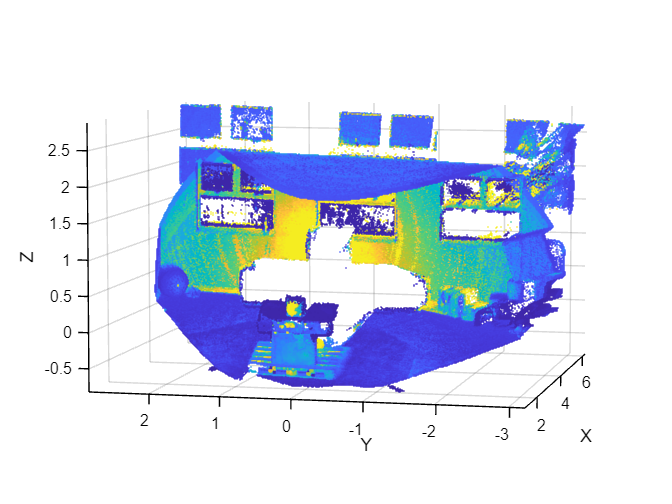

pcshow(cat_pointCloudArray(1),"ColorSource","Intensity","AxesVisibility","on")
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);
 
ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;

z_roi=[-inf,1];
y_roi=[-3,3];
x_roi=[1.2,3];
roi=[x_roi,y_roi,z_roi];

tic
%[cat_pointCloudArray] = cropMerge(roi,80,all_cloudsLiDAR);
[cat_pointCloudArray_cropped] = cropMerge(roi,80,dummyArr);
toc

Elapsed time is 0.431981 seconds.


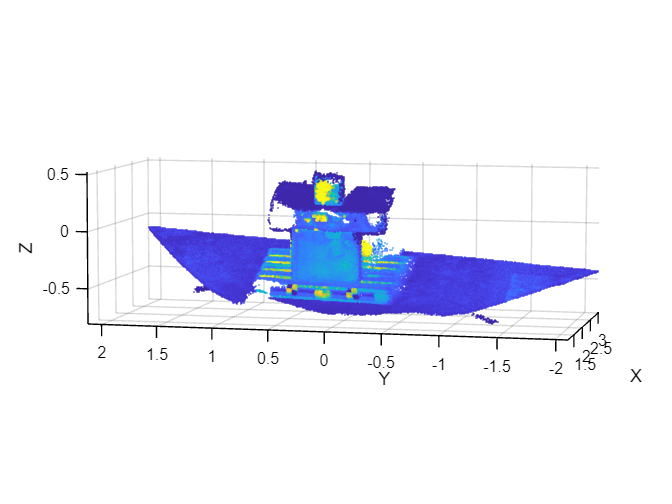

pcshow(cat_pointCloudArray_cropped(1),"ColorSource","Intensity","AxesVisibility","on")
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);
 
ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;

maxDistance=0.02;
MaxNumTrials=3000;
referenceVector=[0, 0, 1];
[model1,inlierIndices,outlierIndices] = pcfitplane(cat_pointCloudArray_cropped(1),maxDistance,referenceVector,MaxNumTrials);

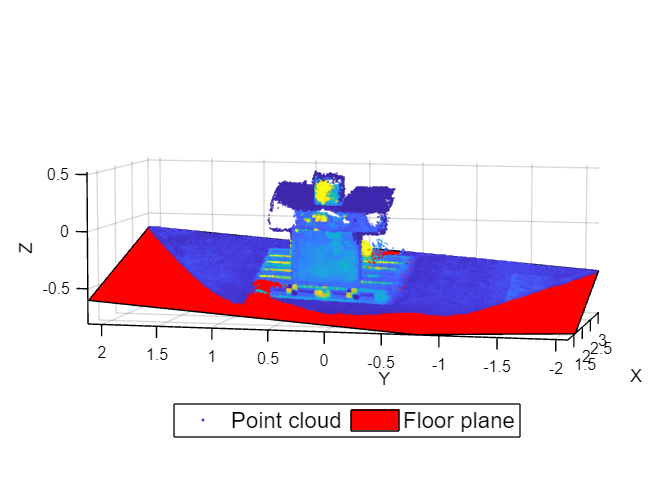

pcshow(cat_pointCloudArray_cropped(1),"ColorSource","Intensity","AxesVisibility","on")
xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);
 
ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;
hold on
plot(model1)
lgd = legend('Point cloud', 'Floor plane', 'Location', 'south');
lgd.FontSize = 14;       % Increase font size
lgd.NumColumns = 2;      % Spread items horizontally
%legend('Point cloud', 'Floor plane','Location', 'south')
hold off

[ptCloudRotated, tform] = rotatePlane(cat_pointCloudArray_cropped(1), model1);

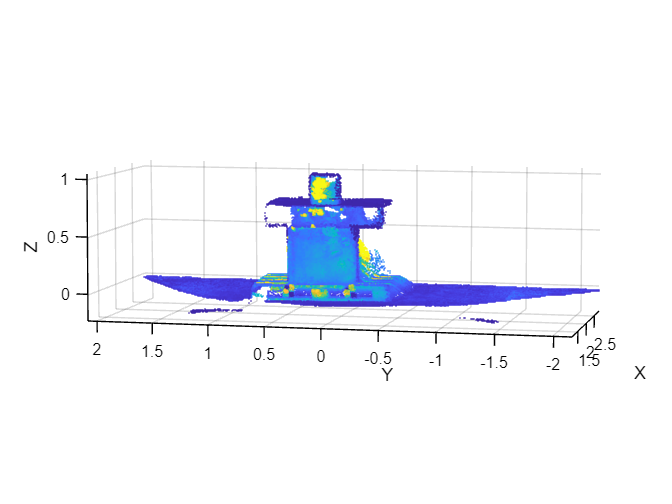


pcshow(ptCloudRotated,"ColorSource","Intensity","AxesVisibility","on")
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);
 
ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;

xLimits = ax.XLim;
yLimits = ax.YLim;
zLimits = ax.ZLim;

% for k=1:8
%     [floorAlign,tform]=alignFloorTform(arrCloudTrans(k));
%     floorTforms{k}=tform;
%     invTform = invert(tform);
%     %crop floor out
%     [sortedPOI,arrIndex,palletIndex,floorIndex,surfIndex] = normsAnalysis(floorAlign);
%     croppedClouds(k)=cropCloud(floorAlign,[-inf,inf],[-inf,inf],[sortedPOI(floorIndex+1)+0.02,inf]);
%     croppedRotated(k)=pctransform(croppedClouds(k),invTform);
% end

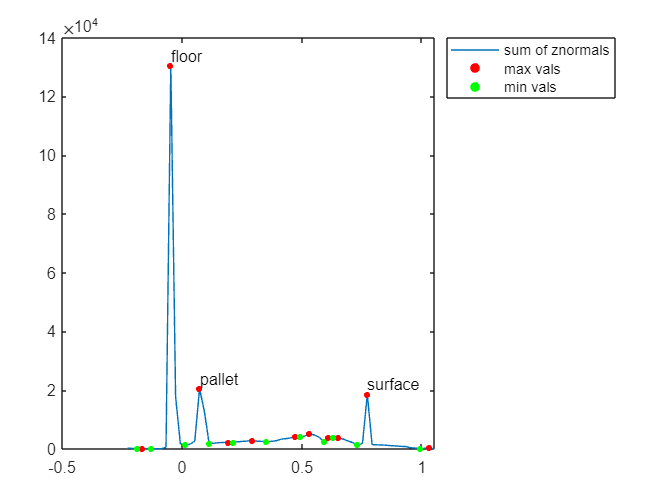

[sortedPOI,arrIndex,palletIndex,floorIndex,surfIndex] = normsAnalysis(ptCloudRotated,'true');

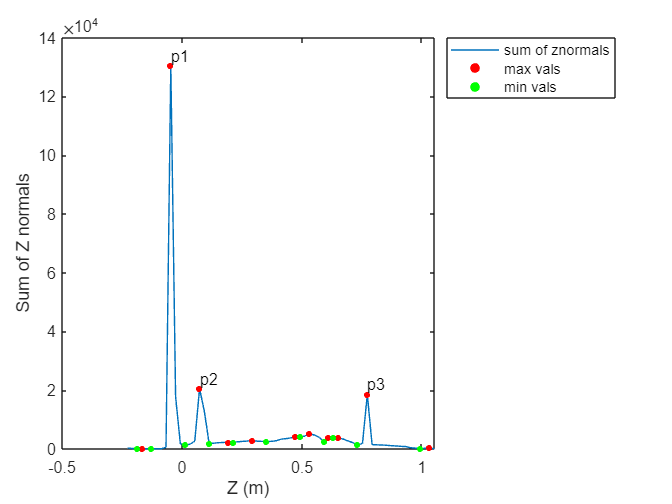

[POI,p1Index,p2Index,p3Index] = zNormsAnalysis(ptCloudRotated,'true');


cropTest=cropCloud(ptCloudRotated,[-inf,inf],[-inf,inf],[POI(p1Index+1)+0.02,inf]);

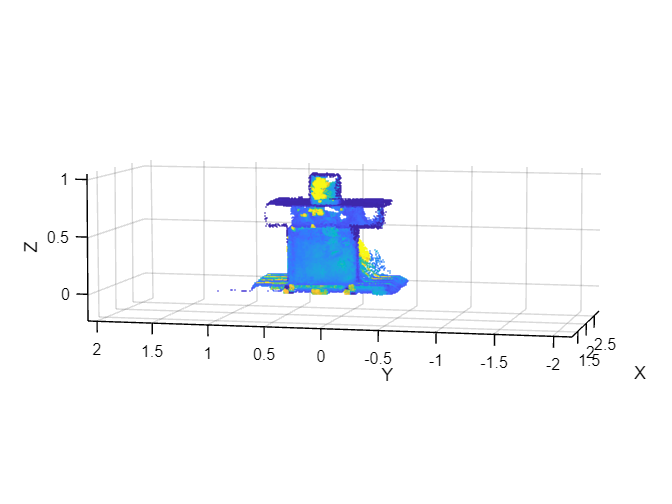

pcshow(cropTest,"ColorSource","Intensity","AxesVisibility","on")
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);
 
ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle
ax.XLim = xLimits;
ax.YLim = yLimits;
ax.ZLim = zLimits;

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;

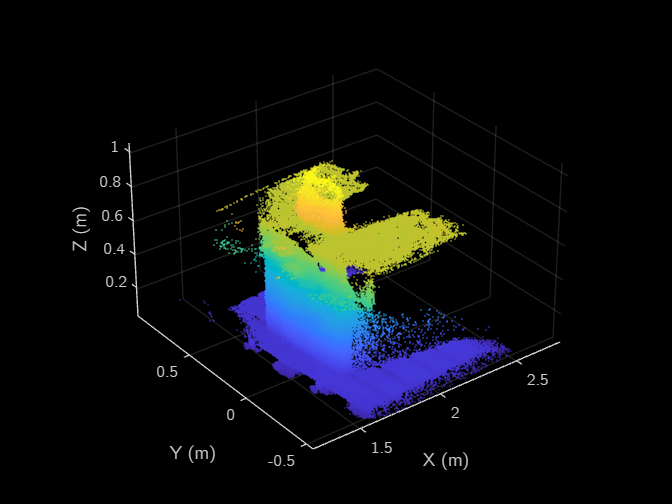

pcDisplay(cropTest);

[cat_pointCloudArray_croppedTen] = cropMerge(roi,10,dummyArr);
[cat_pointCloudArray_croppedSingle] = cropMerge(roi,1,dummyArr);
[cat_pointCloudArray_croppedFifty] = cropMerge(roi,50,dummyArr);

z_roi=[-inf,inf];
y_roi=[-inf,inf];
x_roi=[-inf,inf];

roi=[x_roi,y_roi,z_roi];
[cat_pointCloudArray_Ten] = cropMerge(roi,10,dummyArr);
%[cat_pointCloudArray_Single] = cropMerge(roi,1,dummyArr);
[cat_pointCloudArray_Fifty] = cropMerge(roi,50,dummyArr);

[cat_pointCloudArray_Five] = cropMerge(roi,5,dummyArr);

testview=all_cloudsLiDAR{5};

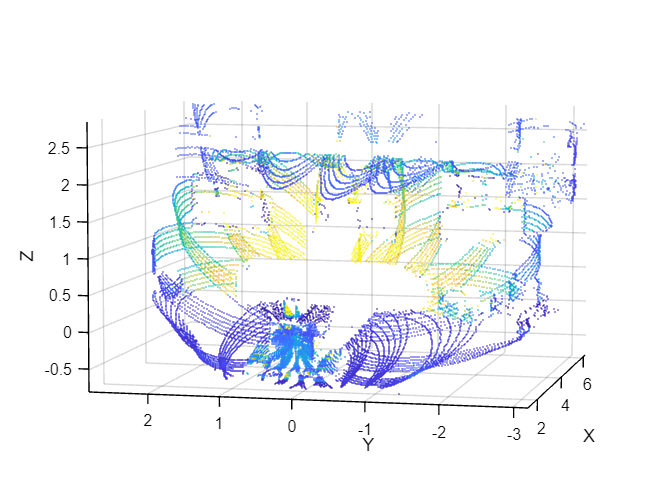

pcshow(testview{1,1},"ColorSource","Intensity","AxesVisibility","on")
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);
 
ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;

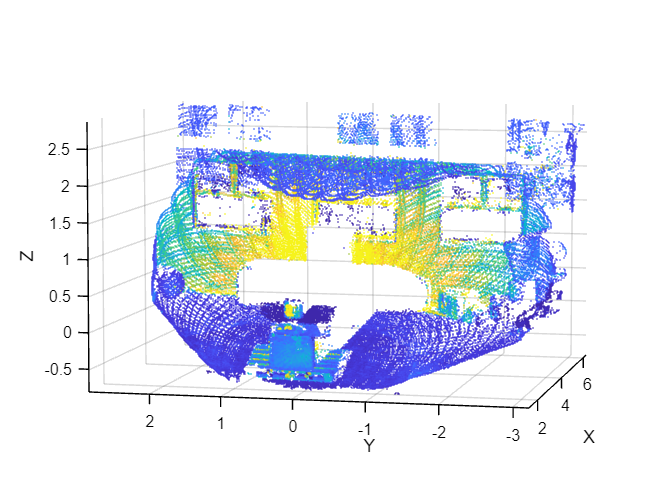

pcshow(cat_pointCloudArray_Five(1),"ColorSource","Intensity","AxesVisibility","on")
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);
 
ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;

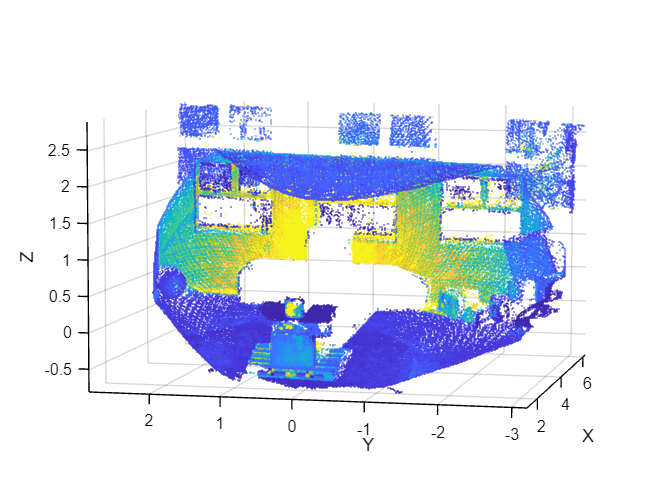

pcshow(cat_pointCloudArray_Ten(1),"ColorSource","Intensity","AxesVisibility","on")
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);
 
ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;

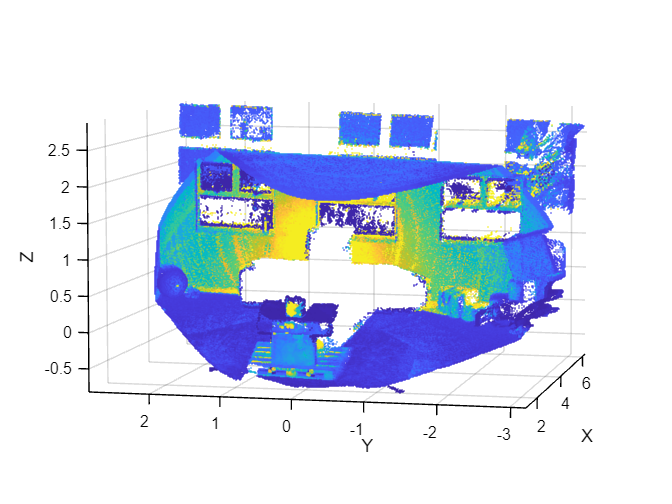

pcshow(cat_pointCloudArray_Fifty(1),"ColorSource","Intensity","AxesVisibility","on")
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);
 
ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;

pcDownsample1CM=pcdownsample(cat_pointCloudArray_cropped(1),"gridAverage",0.1);
pcDownsample5CM=pcdownsample(cat_pointCloudArray_cropped(1),"gridAverage",0.5);
pcDownsample5MM=pcdownsample(cat_pointCloudArray_cropped(1),"gridAverage",0.05);
pcDownsample1MM=pcdownsample(cat_pointCloudArray_cropped(1),"gridAverage",0.01);

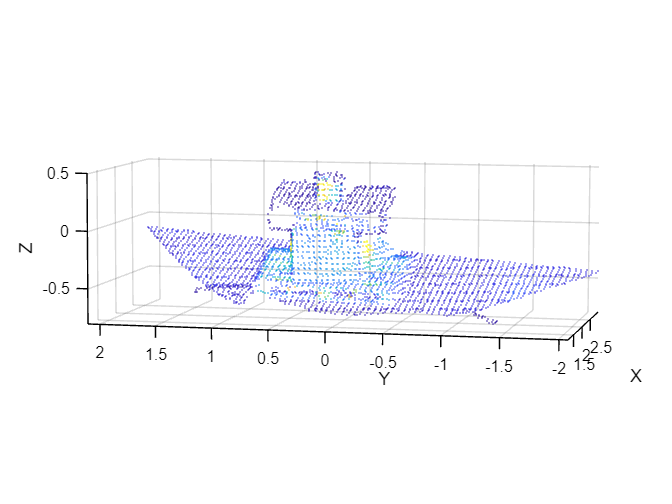

pcshow(pcDownsample5MM,"ColorSource","Intensity","AxesVisibility","on")
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);
 
ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;

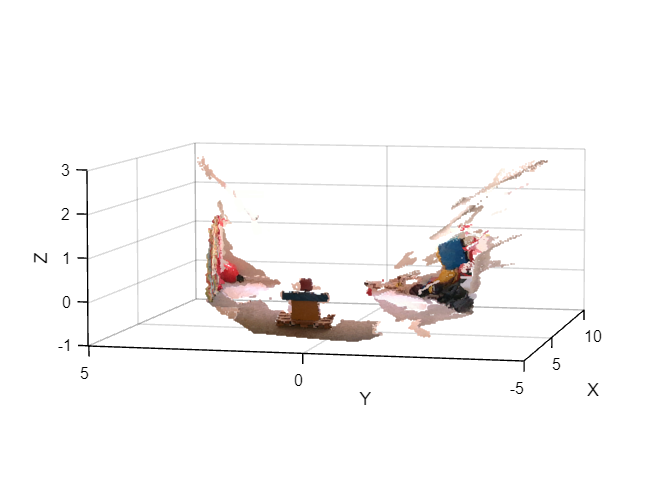

pcshow(arrRSraw{5},"AxesVisibility","on")
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);
z_roi=[-1,1];
y_roi=[-3,3];
x_roi=[1.2,3];

z_roibig=[-1,3];
y_roibig=[-5,5];
x_roibig=[1.2,10];
%z_roi=[-inf,inf];
%y_roi=[-inf,inf];
%x_roi=[-inf,inf];

roi=[x_roi,y_roi,z_roi];

%zlim(z_roi);
%ylim(y_roi);
%xlim(x_roi);

zlim(z_roibig);
ylim(y_roibig);
xlim(x_roibig);
 
ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;

roibig=[x_roibig,y_roibig,z_roibig];
RSbig=cropSingleCloud(arrRSraw{5},roibig);

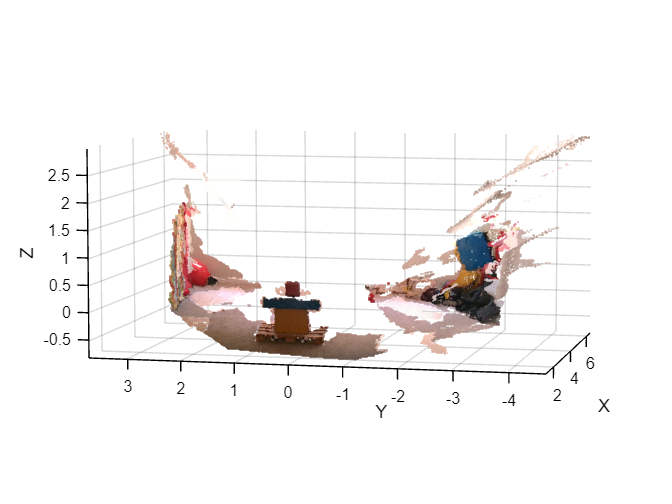

pcshow(RSbig,"AxesVisibility","on")
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);
 
ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;

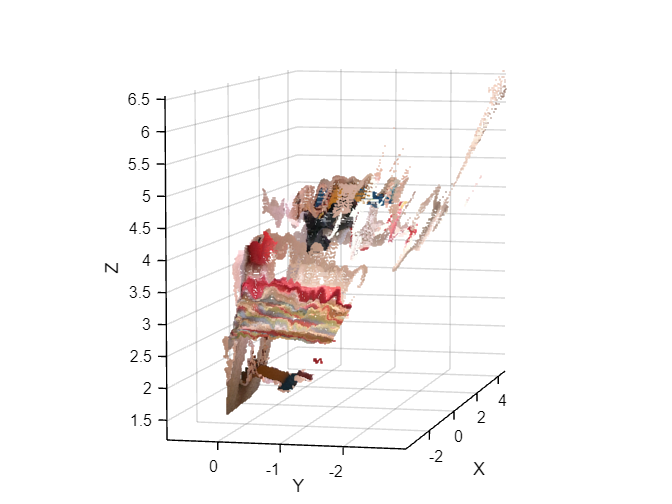

RSbefore=LiDAR_to_realsense_ros2(RSbig);
pcshow(RSbefore,"AxesVisibility","on")
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);
 
ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;

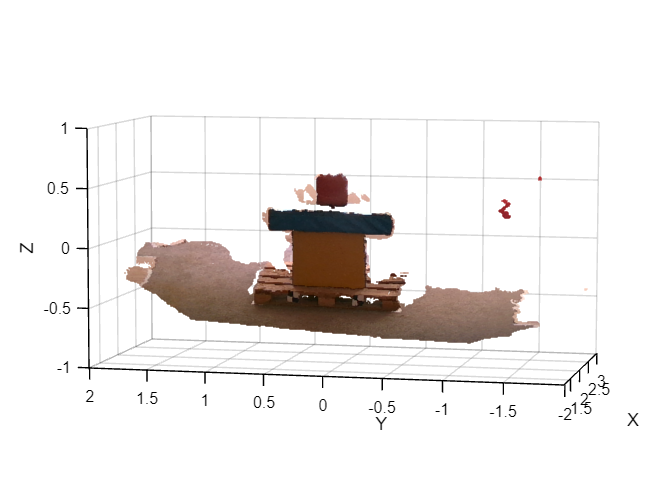

pcshow(RSbig,"AxesVisibility","on")
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);
z_roi=[-1,1];
y_roi=[-2,2];
x_roi=[1.2,3];


roi=[x_roi,y_roi,z_roi];

zlim(z_roi);
ylim(y_roi);
xlim(x_roi);

ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;

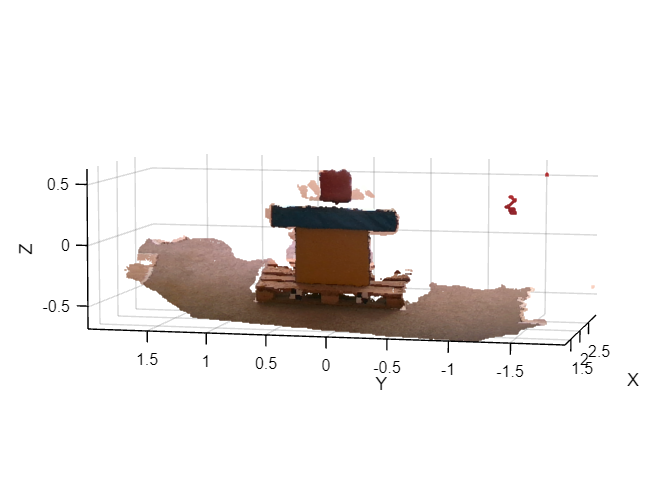

RScropped=cropSingleCloud(RSbig,roi);
pcshow(RScropped,"AxesVisibility","on")
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);


ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;

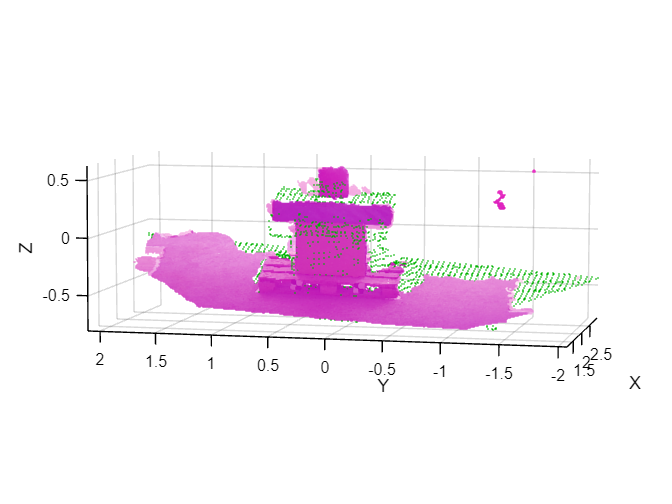

pcshowpair(RScropped,pcDownsample5MM,"AxesVisibility","on");
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view([-76.87 6.18]);


ax = gca; % Get the current axes handle
fig = gcf; % Get the current figure handle

% Set background color to white
fig.Color = 'white';

% Set axes properties
ax.Color = 'white'; % Axes background
ax.XColor = 'black'; % X-axis color
ax.YColor = 'black'; % Y-axis color
ax.ZColor = 'black'; % Z-axis color
ax.GridColor = 'black'; % Grid line color
ax.MinorGridColor = 'black'; % Minor grid line color (if enabled)

% Optional: Enable grid if not already on
grid on;

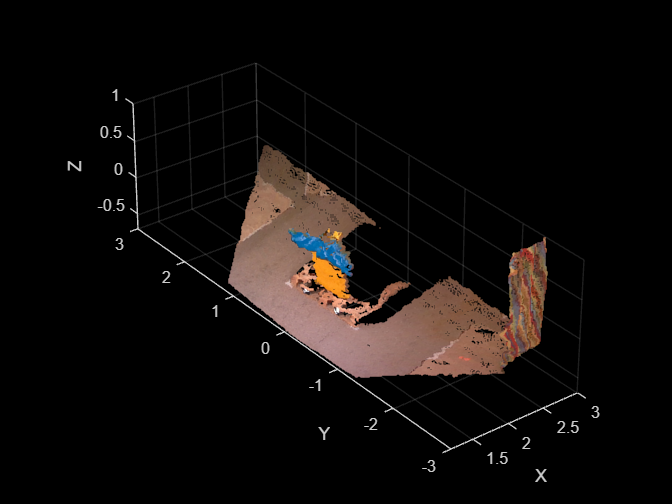

rstest=realsense_to_LiDAR_ros2(arrRSraw{1,1});
pcshow(rstest,"AxesVisibility","on")
xlabel('X');
ylabel('Y');
zlabel('Z');

zlim(z_roi);
ylim(y_roi);
xlim(x_roi);

indices=findPointsInROI(rstest,roi);
rstestcrop=select(rstest, indices);

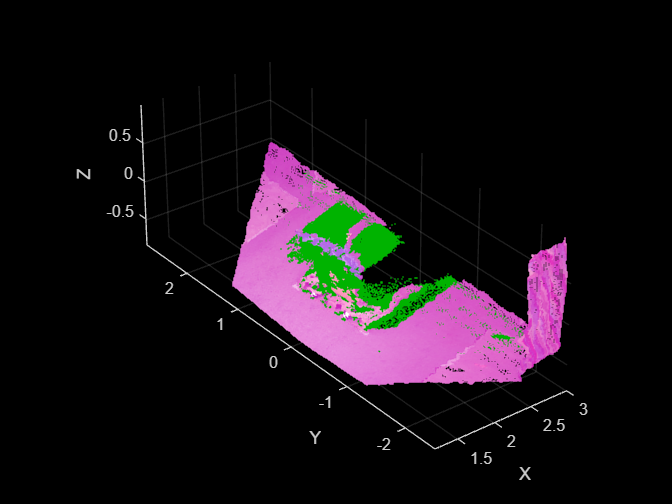

pcshowpair(rstestcrop,cat_pointCloudArray(1),"AxesVisibility","on")
xlabel('X');
ylabel('Y');
zlabel('Z');

## Displaying your final clouds

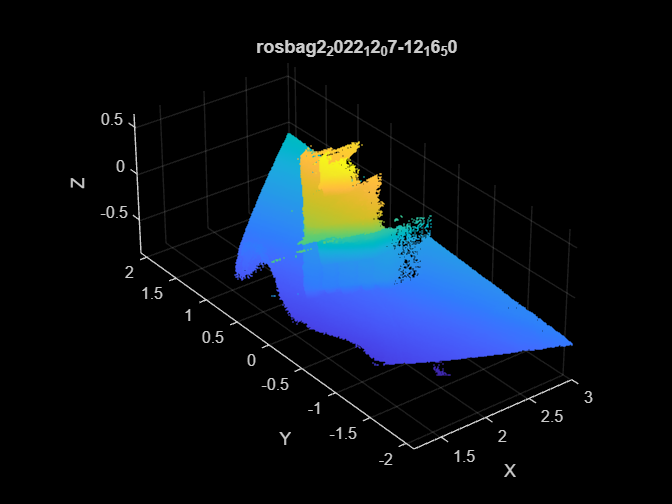

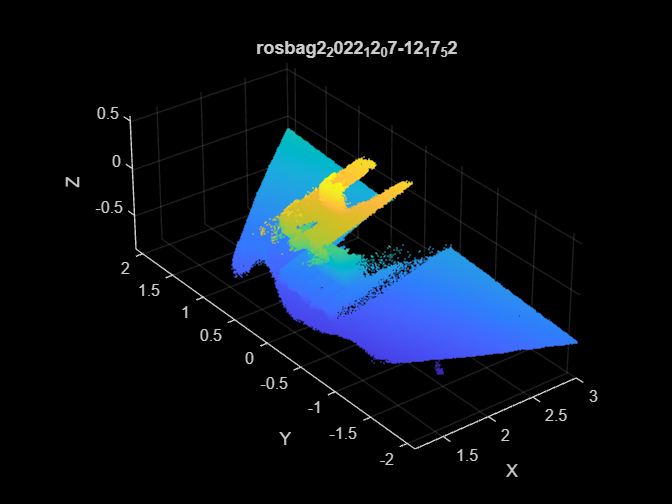

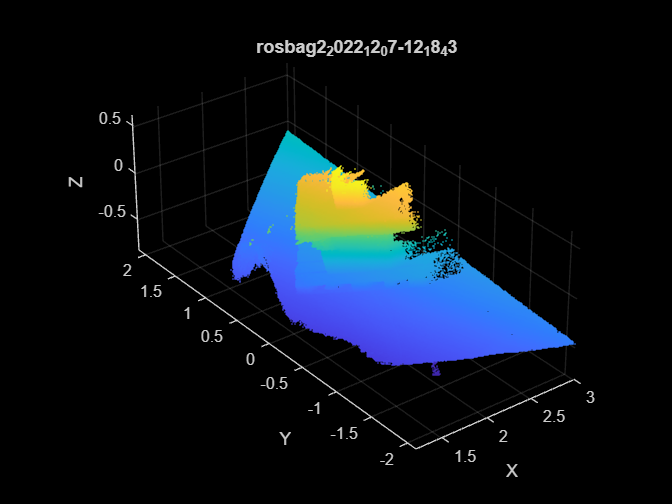

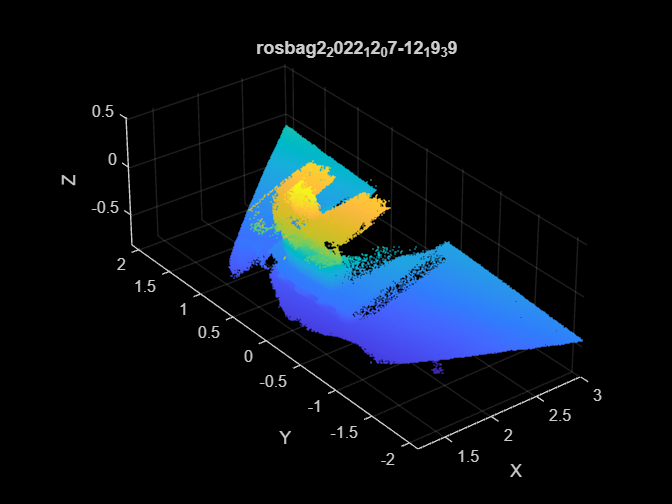

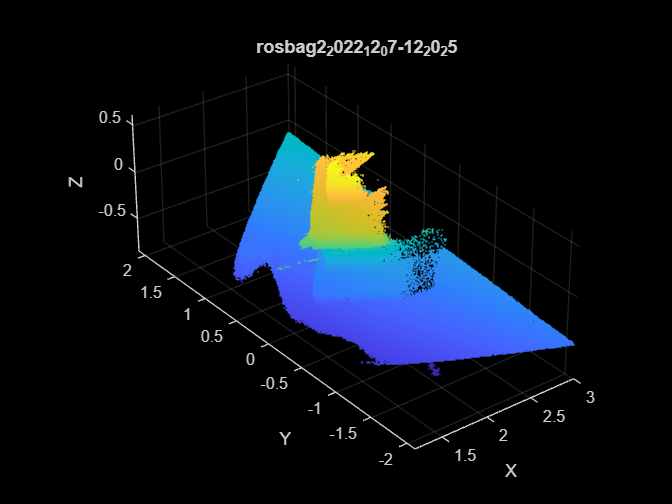

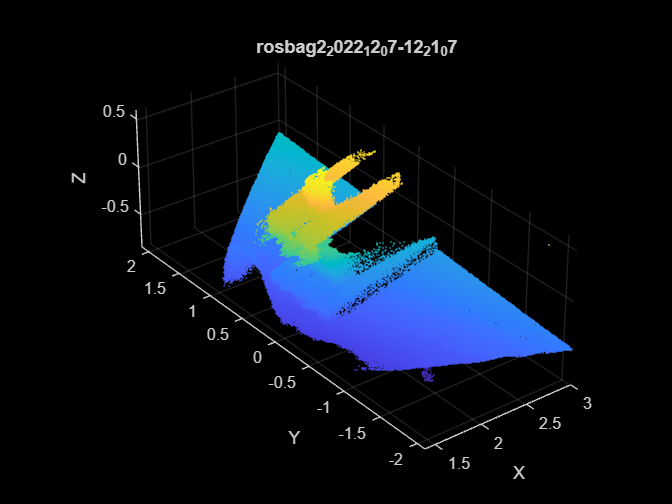

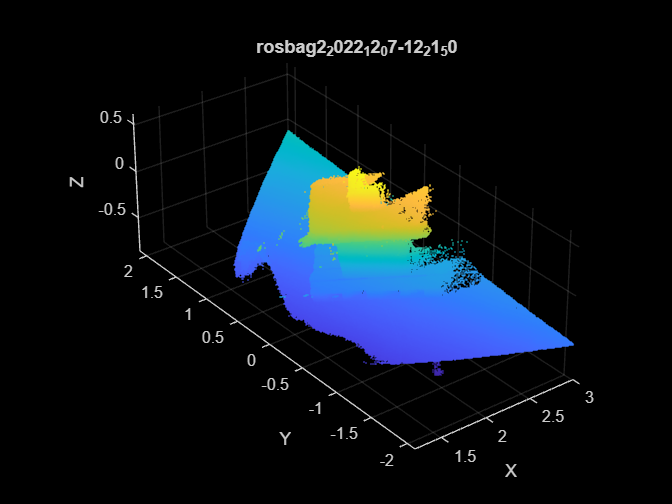

nviews=length(all_cloudsLiDAR);
for k=1:nviews
    figure
    pcshow(cat_pointCloudArray(k),"AxesVisibility","on")
    title(fnames(k))
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
end

## Saving the raw data for future use

save("Pancake3Data");